# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu

Max Planck - University of Toronto Centre

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de}

Version: 2400801

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1), the post-op CT scan (hereafter referred to as CT), and *optionally, the pre-op T2-weighted MRI scan (hereafter referred to as T2)*. The scans should be in DICOM (.dcm) or NIFTI (.nii) format.

- Make sure that .dcm files in one folder all belong to the same scan (i.e., create dedicated T1/T2/CT folders when preparing DICOM files)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

cfg.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

cfg.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

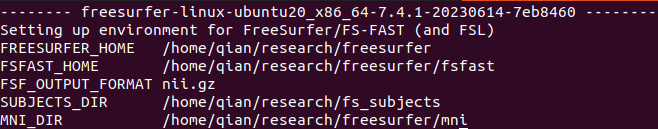

Type patient ID below:

pat.id  = "TWH238";

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
cfg.dir_el          = strjoin(elec_loc_path_parts(1:end-1), filesep);
addpath(fullfile(cfg.dir_el, 'functions'))
[cfg, pat] = el_init(cfg, pat);

## Import and preprocess scans

Say goodbye to manual preprocessing and coregistration of anatomical scans! The script here imports the T1, CT (and optionally T2) scans into a FreeSurfer subject folder. Moreover, it performs automatic scan centering, AC-PC alignment, coregistration, and defacing. The resulting scans are ready for electrode localization and data sharing.

### Procedure

- Run this section.

- ([UI prompt] [If preprocessed files already exist in the output folder] Indicate whether you want to re-import and re-preprocess the scans. If you choose no, the section will simply read and print the paths to preprocessed scans)

- [UI prompt] Indicate whether you have a T2 to include.

- [UI prompt] Indicate whether you want to import DICOM or NIFTI files.

- [UI file/directory selection] Select T1, CT (and T2) one by one according to prompt in the dialog title. For DICOM, you need to select a folder containing all .dcm files corresponding to one scan. For NIFTI, you need to select a single .nii file.

- Wait for processing. Before the T1 defacing stage, a message window will pop up with instructions on how to proceed.

- During CT processing, a viewer window will pop up to let you inspect the CT scan. You can adjust the minimum value to roughly determine an intensity threshold such that only bones and electrodes are visible to effectively de-identify the patient. Enter the value into the textbox.

- A viewer window will pop up at the end to allow you to inspect the scans overlaid on top of grayscale T1. The scans should be aligned to each other and defaced. Close the window when done inspecting.

### Output

- The elec_loc subfolder (`pat.dir.el`) in FreeSurfer subject folder with preprocessed (AC-PC aligned, defaced, and co-registered) scans. Scan file names comply with BIDS format (e.g., *sub-XXX_acq-preop_T1w.nii*). Compressed scans (.nii.gz) are further available in elec_loc/BIDS_outputs/anat.

- Updated `pat` structure.

Validating 194 files ... (192 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH238'
 x2_25_108005656364504089028975980666127903890             320x320x192x1
Elapsed time by dicm2nii is 3.2 seconds

Validating 211 files ... (211 valid)
Converting 1 series (Canon) into 4-D .nii: subject 'TWH238'
 x2_25_1625091693553315394048118947240948887             512x512x211x1
Elapsed time by dicm2nii is 5.0 seconds

Validating 45 files ... (43 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH238'
 x2_25_302317991430832854717406897800285056335             480x480x43x1
Elapsed time by dicm2nii is 1.1 seconds

**********PROCESSING T1**********

>>>>>Centering /home/qian/Desktop/Patient DICOMs/TWH238/T1/x2_25_108005656364504089028975980666127903890.nii
>>>>>Centered scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T1w_cent.nii

>>>>>Aligning /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T1w_cent.nii to AC-PC

Affine reorientat

>>>>>Defaced scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T1w_cent_acpc_deface.nii

**********PROCESSING CT**********

>>>>>Centering /home/qian/Desktop/Patient DICOMs/TWH238/CT_axial1mm/x2_25_1625091693553315394048118947240948887.nii
>>>>>Centered scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent.nii

>>>>>Coregistering /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent.nii to /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T1w_cent_acpc.nii

SPM12: spm_coreg (v6435)                           16:59:17 - 24/06/2025
Completed                               :          16:59:44 - 24/06/2025

>>>>>Coregistered scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent_coreg.nii

>>>>>Masking /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent_coreg.nii according to /ho

ans = struct with fields:
      fname: '/home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent_coreg_deface_thres.nii'
        dim: [512 512 211]
         dt: [4 0]
      pinfo: [3×1 double]
        mat: [4×4 double]
          n: [1 1]
    descrip: 'spm - algebra'
    private: [1×1 nifti]



>>>>>Thresholded scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_CT_cent_coreg_deface_thres.nii

**********PROCESSING T2**********

>>>>>Centering /home/qian/Desktop/Patient DICOMs/TWH238/T2/x2_25_302317991430832854717406897800285056335.nii
>>>>>Centered scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T2w_cent.nii

>>>>>Coregistering /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T2w_cent.nii to /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T1w_cent_acpc.nii

SPM12: spm_coreg (v6435)                           16:59:54 - 24/06/2025
Completed                               :          17:00:03 - 24/06/2025

>>>>>Coregistered scan saved at /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T2w_cent_coreg.nii

>>>>>Masking /home/qian/research/fs_subjects/TWH238/elec_loc/temp_sub-TWH238_T2w_cent_coreg.nii accordin

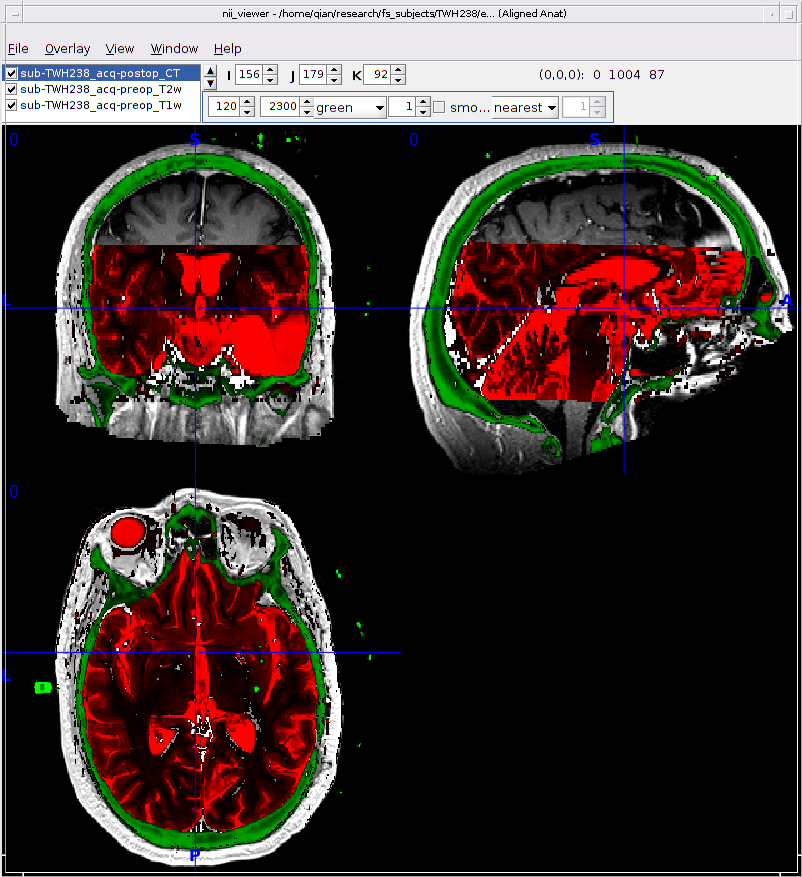

pat = el_import_scans(pat);

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section launches iElectrodes.    

Welcome to iElectrodes.
iElectrodes toolbox is FOR RESEARCH PURPOSES ONLY. This software is
for research purposes only and has NOT BEEN APPROVED FOR CLINICAL USE.
Help about using iElectrodes can be found online in 
https://sourceforge.net/p/ielectrodes/wiki/Home/
You have the last version of iElectrodes :-)
Project estructure is beeing checked...
Checking done.


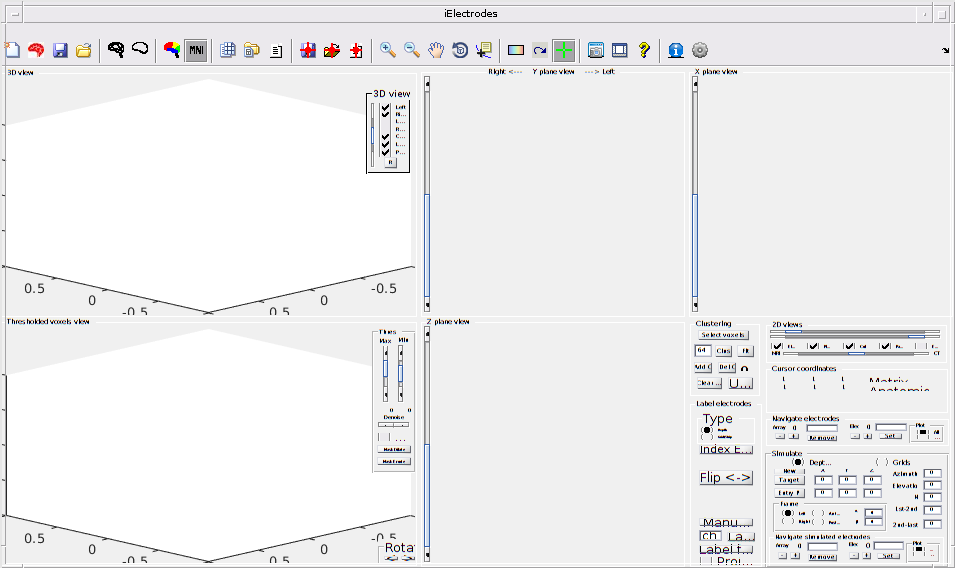

cd(pat.dir.el)
electrodes_gui

### iElectrodes toolbars

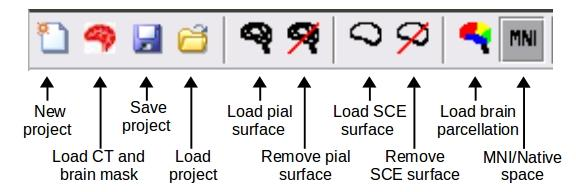

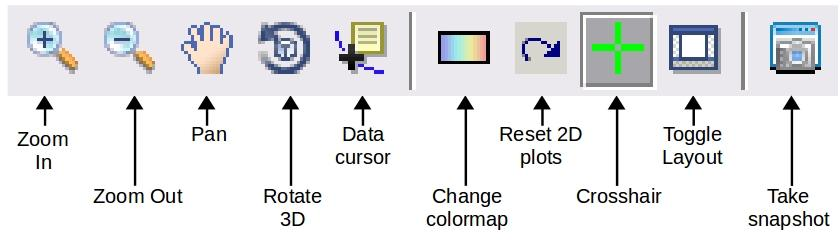

### Steps

- Click "New project" (see icon above) and load *sub-XXX_T1w.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan *sub-XXX_CT.nii.*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- When you are done, save the project (see icon above) and name it as *sub-XXX.iel*. You can also save the project halfway and reload it using the "Load project" button.

## FreeSurfer recon-all with optional subfield segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

`recon-all` is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

Freesurfer also has a hippocampus/amygdala subfield segmentation feature ([https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala)) with flexible scan input options (use T1 and/or T2).

### Inputs

- [Auto-loaded] Defaced, AC-PC aligned T1 (and T2)

- [Select from dropdown box] hippocampus and amygdala subfield segmentation option. It's recommended to select both T1 + T2 if you have both.

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

subfield_seg_mode = 'T1+T2';
if contains(subfield_seg_mode, 'T2') && ~isfield(pat.t2, 'image')
    error('T2 was requested for subfield segmentation but no T2 was loaded in pat')
elseif ~exist(pat.t2.image, 'file')
    error('T2 was requested for subfield segmentation but scan not found')
end
el_fs_recon_all(cfg, pat)

mri_convert /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_acq-preop_T1w.nii /home/qian/research/fs_subjects/TWH238/mri/orig/001.mgz 
reading from /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_acq-preop_T1w.nii...
TR=0.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-0.997658, 0.0544272, -0.0414158)
j_ras = (0.0642866, 0.952939, -0.296268)
k_ras = (-0.0233456, 0.298238, 0.954206)
writing to /home/qian/research/fs_subjects/TWH238/mri/orig/001.mgz...
fs-check-version --s TWH238 --o /tmp/tmp.DohnpF
Tue Jun 24 17:25:18 EDT 2025

setenv SUBJECTS_DIR /home/qian/research/fs_subjects
cd /home/qian/research/fs_subjects/TWH238/elec_loc
/home/qian/research/freesurfer/bin/fs-check-version --s TWH238 --o /tmp/tmp.DohnpF
-rwxrwxr-x 1 qian qian 18565 Jun 14  2023 /home/qian/research/freesurfer/bin/fs-check-version

freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
$Id$
Linux N2B-KDT 5.15.0-139-generic #149~20.04.1-Ubuntu SMP Wed Apr 16 08:29:56 UTC 2025 x86_64 x86_64 x86

el_fs_hpc_amy_seg(cfg, pat, subfield_seg_mode)

#--------------------------------------------
#@# Hippocampal Subfields processing (T1+T2) left Tue 24 Jun 2025 10:58:15 PM EDT
------------------------------------------
Setting up environment variables
---
LD_LIBRARY_PATH is .:/home/qian/research/freesurfer/MCRv97//runtime/glnxa64:/home/qian/research/freesurfer/MCRv97//bin/glnxa64:/home/qian/research/freesurfer/MCRv97//sys/os/glnxa64:/usr/local/MATLAB/R2023a/sys/os/glnxa64:/usr/local/MATLAB/R2023a/bin/glnxa64:/home/qian/.MathWorks/4Vk9Oh6kZxYaiwRuMNjXunaMDRFaFa9VGJLCsZUPZOM/bin/glnxa64:/usr/local/MATLAB/R2023a/extern/lib/glnxa64:/usr/local/MATLAB/R2023a/cefclient/sys/os/glnxa64:/usr/local/MATLAB/R2023a/sys/java/jre/glnxa64/jre/lib/amd64/native_threads:/usr/local/MATLAB/R2023a/sys/java/jre/glnxa64/jre/lib/amd64/server:/home/qian/research/freesurfer/MCRv97//sys/opengl/lib/glnxa64:/usr/local/MATLAB/R2023a/sys/os/glnxa64:/usr/local/MATLAB/R2023a/bin/glnxa64:/home/qian/.MathWorks/4Vk9Oh6kZxYaiwRuMNjXunaMDRFaFa9VGJLCsZUPZOM/bin/glnxa64:/us

## Convert .mgz to .nii and create bilateral meshes

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in FreeSurfer *mri* subfolder

- [Auto-loaded] xh.white and xh.pial.T1 files in FreeSurfer *surf* subfolder

### Outputs

- .nii files in FreeSurfer *mri* subfolder

- bil_white.nv and bil_pial.nv in *elec_loc* subfolder

el_mgz2nii(cfg, pat)

Converting .mgz to .nii in /home/qian/research/fs_subjects/TWH238/mri
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH238/mri/aparc.DKTatlas+aseg.mgz /home/qian/research/fs_subjects/TWH238/mri/aparc.DKTatlas+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH238/mri/aparc.DKTatlas+aseg.mgz...
TR=0.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, 4.19095e-09, -1.86265e-09)
j_ras = (-3.72529e-09, 2.98023e-08, -1)
k_ras = (0, 1, 0)
Setting output orientation to RAS
Reslicing using trilinear interpolation 
writing to /home/qian/research/fs_subjects/TWH238/mri/aparc.DKTatlas+aseg.nii...
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH238/mri/aparc.a2009s+aseg.mgz /home/qian/research/fs_subjects/TWH238/mri/aparc.a2009s+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH238/mri/aparc.a2009s+aseg.mgz

el_merge_mesh(pat)

Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH238/elec_loc/bil_white.nv
Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH238/elec_loc/bil_pial.nv


## Read localization results from .iel

### Input

- [Select from GUI] iElectrodes project .iel file

### Output

- Updated `pat` structure with new field `elec`

pat = el_get_elec(pat);

Electrode group: LAHC
	LAHC1 | LAHC2 | LAHC3 | LAHC4 | LAHC5 | LAHC6 | LAHC7 | LAHC8
Electrode group: RTO
	RTO1 | RTO2 | RTO3 | RTO4 | RTO5 | RTO6 | RTO7 | RTO8
Electrode group: ROFC
	ROFC1 | ROFC2 | ROFC3 | ROFC4 | ROFC5 | ROFC6 | ROFC7 | ROFC8
Electrode group: RF
	RF1 | RF2 | RF3 | RF4 | RF5 | RF6 | RF7 | RF8
Electrode group: RAINS
	RAINS1 | RAINS2 | RAINS3 | RAINS4 | RAINS5 | RAINS6 | RAINS7 | RAINS8
Electrode group: RMINS
	RMINS1 | RMINS2 | RMINS3 | RMINS4 | RMINS5 | RMINS6 | RMINS7 | RMINS8
Electrode group: RPINS
	RPINS1 | RPINS2 | RPINS3 | RPINS4 | RPINS5 | RPINS6 | RPINS7 | RPINS8
Electrode group: RPOST
	RPOST1 | RPOST2 | RPOST3 | RPOST4 | RPOST5 | RPOST6 | RPOST7 | RPOST8
Electrode group: RSMG
	RSMG1 | RSMG2 | RSMG3 | RSMG4 | RSMG5 | RSMG6 | RSMG7 | RSMG8
Electrode group: RANG
	RANG1 | RANG2 | RANG3 | RANG4 | RANG5 | RANG6 | RANG7 | RANG8


## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- Updated MATLAB structure `elec` with microwires

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3;
pat.elec = el_est_micro(pat.elec, micro_to_macro_dist);

No microwire found for LAHC     Estimating... 
	LAHCu [-26.25, -18.68, -7.33]
No microwire found for RTO      Estimating... 
	RTOu [33.14, -62.69, -3.84]
No microwire found for ROFC     Estimating... 
	ROFCu [6.54, 43.90, -7.83]
No microwire found for RF       Estimating... 
	RFu [14.26, 47.53, 2.85]
No microwire found for RAINS    Estimating... 
	RAINSu [35.36, 1.73, 1.03]
No microwire found for RMINS    Estimating... 
	RMINSu [35.99, -6.75, 2.38]
No microwire found for RPINS    Estimating... 
	RPINSu [31.62, -21.40, 4.54]
No microwire found for RPOST    Estimating... 
	RPOSTu [28.11, -46.79, -1.76]
No microwire found for RSMG     Estimating... 
	RSMGu [15.65, -30.11, 35.25]
No microwire found for RANG     Estimating... 
	RANGu [27.07, -40.83, 29.32]
10 microwire location estimated.


## [If re-referencing with bipolar setup] Estimate virtual electrode location

Estimate the middle point between adjacent contacts for each depth electrode and add it to the electrodes structure with type `bipolar`

### **Input**

- [Auto-loaded] MATLAB structure `elec`

### **Output**

- Updated MATLAB structure `elec` with virtual electrodes

pat.elec = el_bipolar(pat.elec);

Estimated location for depth electrode 	LAHC
Estimated location for depth electrode 	RTO
Estimated location for depth electrode 	ROFC
Estimated location for depth electrode 	RF
Estimated location for depth electrode 	RAINS
Estimated location for depth electrode 	RMINS
Estimated location for depth electrode 	RPINS
Estimated location for depth electrode 	RPOST
Estimated location for depth electrode 	RSMG
Estimated location for depth electrode 	RANG


## Visualize electrode locations on native T1 and CT

### Output

- Figures for each channel in the subfolder *elec_loc/slice_views*

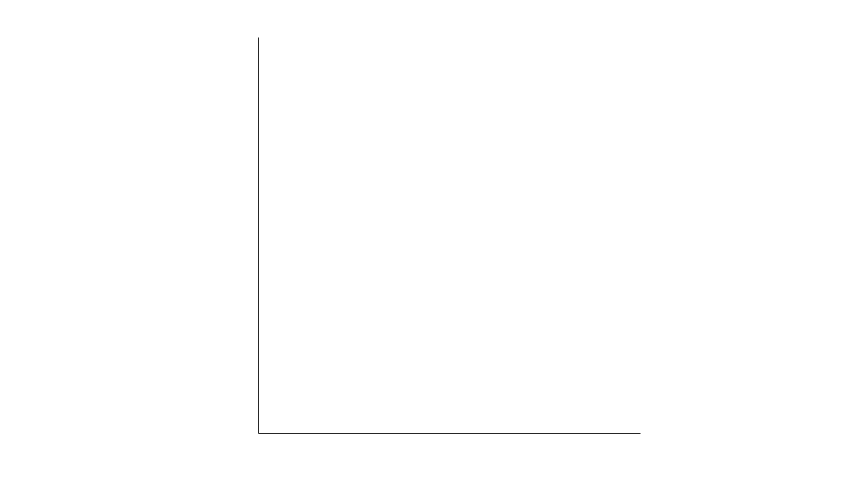

el_slice_view(pat)

## Get FreeSurfer labels in the native space

The main purpose of running FreeSurfer recon-all is to produce automated cortical parcellation. By combining electrode location with the parcellations, we can automatically assign them anatomical labels. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.)

The output filenames are BIDS-compliant ([https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv](https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv)). Since results from this section are derived from the patient's native space (which is ACPC aligned), the identifier is `sub-xxx_space-ACPC_electrodes`.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] FreeSurfer parcellation files 

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get FreeSurfer label with iElectrodes' `anatomicLabelFS` function

- Expand to also get hippocampal subfield labels

Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.


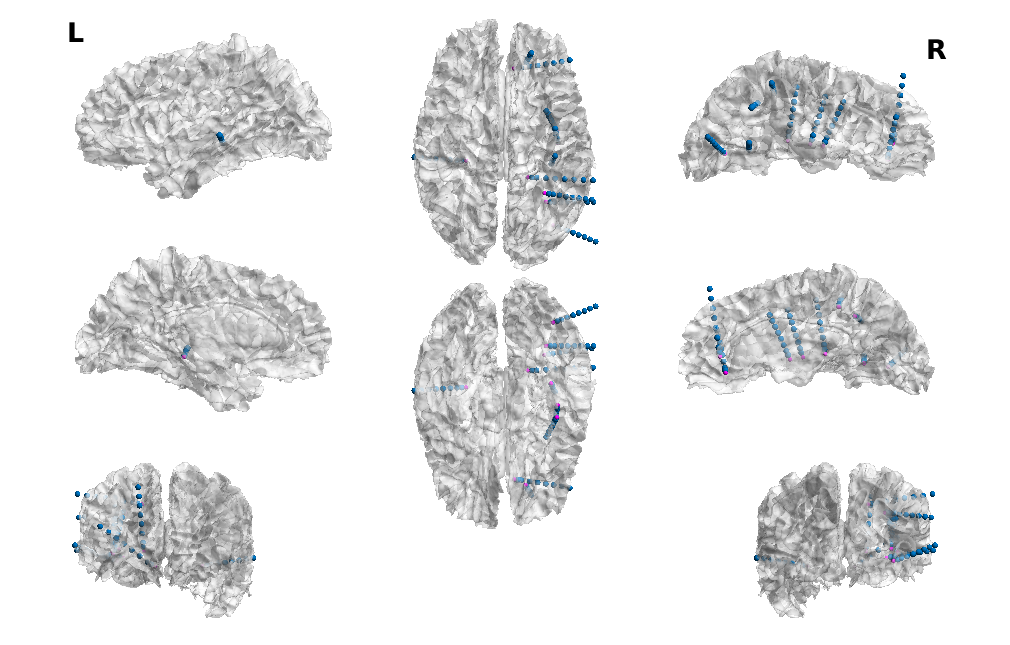

Electrode location (native ACPC space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_space-ACPC_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH238/elec_loc/BIDS_outputs/ieeg/sub-TWH238_space-ACPC_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_space-ACPC_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH238/elec_loc/BIDS_outputs/ieeg/sub-TWH238_acq-ACPCRender_photo.jpg


el_elec_native(cfg, pat)

## Get electrode coordinates in MNI152 space

For group-level visualization of electrode location, mapping locations from native to standardized spaces is necessary. This section does a linear transform to electrode locations to map them to the MNI152 (ICBM152) space.

[https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin](https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin)

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] T1 scan to be registered to MNI152Lin template

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get Harvard-Oxford atlas labels with iElectrodes' `anatomicLabel` function

- Get other labels for the MNI space (e.g. AAL)

Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.


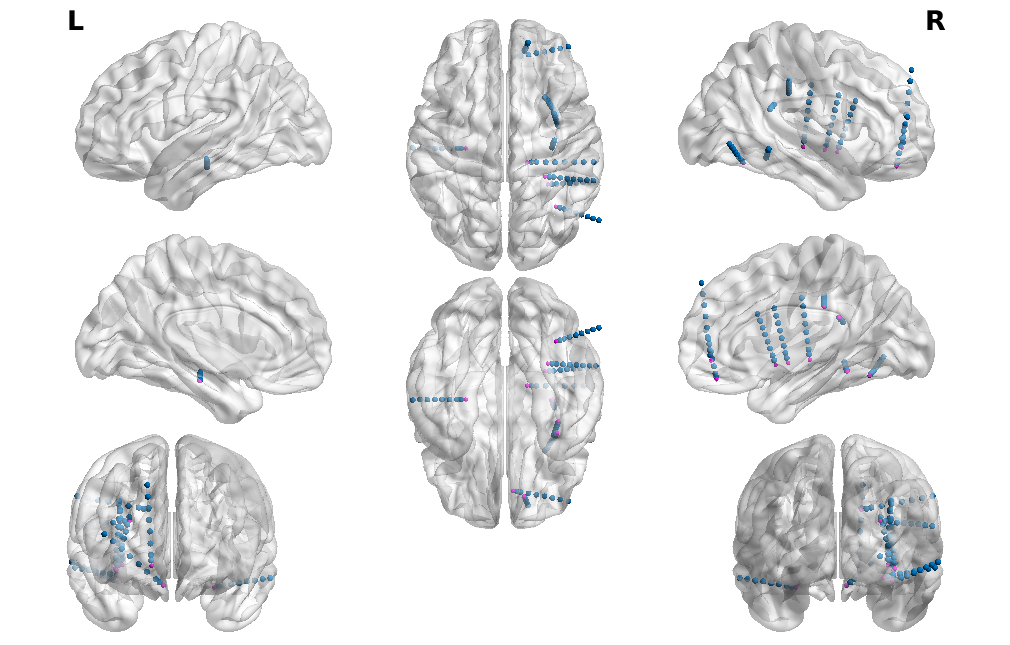

Electrode location (MNI152 space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_space-MNI152Lin_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH238/elec_loc/BIDS_outputs/ieeg/sub-TWH238_space-MNI152Lin_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH238/elec_loc/sub-TWH238_space-MNI152Lin_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH238/elec_loc/BIDS_outputs/ieeg/sub-TWH238_acq-MNI152Render_photo.jpg


el_elec_mni152(cfg, pat)